Parámetros

Ac = 1;         %Amplitud Portadora
Tb = 0.05;      %Tiempo de Bit
sps = 8;      %Muestras por símbolo (Personalizado by us)
Ts = Tb/sps;    %Tiempo de Muestreo
L = 3;          %# de Bits que conforman un Símbolo
fc = 1/(Ts*8); 

Bits

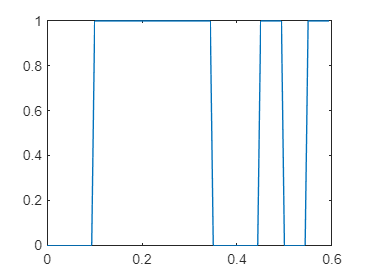

bits = [1 0 1 1 0 0 1 1 1 0 0 1];       %Bits de llegada
NBit = length(bits);                    %Número de Bits 
t = 0:Ts:Tb*NBit-Ts;                    %Tiempo
Nsamples = NBit*sps;                    %Número de Muestras
n = 1:Nsamples;                         %Muestras
[sym, bits] = bit2sym(bits,L);
m_t = vect2samp(bits,sps);
sym_t = vect2samp(sym, sps*L);       
g_t = Ac*exp(1j*sym_t*pi/4);            %Envolvente compleja
x_t = real(g_t);                        %Componente en Fase
y_t = imag(g_t);                        %Componente en cuadratura
s_t = Ac*cos(2*pi*fc*t+sym_t*pi/4);     %Señal Modulada
plot(t,m_t)

Funciones:

function [sym, bitOrder] = bit2sym(bits, L) %Para generar los símbolos
    NBit = length(bits);
    Power2 = 2.^(L-1:-1:0);
    Nsteps = NBit/L;
    sym = zeros(1,Nsteps);
    for i = 1:Nsteps
        BitAct = bits(end-i*L+1:end-(i-1)*L);
        bitOrder((i-1)*L+1:i*L) = BitAct; 
        sym(i) = dot(Power2,BitAct);
    end
end

function m = vect2samp(vect, sps) %Para pasar de los bits al tiempo muestreado
    Nvect = length(vect);
    m = zeros(1, sps*Nvect);
    for i = 1:Nvect
        m((i-1)*sps+1:i*sps) = vect(i);
    end
end